# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

O método de resíduos ponderados consiste em:

- achar um conjunto de funções que satisfaçam as condições de contorno do problema (PVC);

- avaliar uma C. Linear dessas funções de forma, buscando que o resíduo da solução com funções pesos associada a cada direção seja nulo;

- A diferentes tipos de funções de forma que podem ser utilizadas, nesse código, utilizou-se: Método da colocação

Número de graus de liberdade:

for m=2:4

Tamanho do domínio trabalhado:

left=0;
right=1;

Malha para os pontos do metodo de colocação:

xmesh=linspace(left,right,m+2);

Vetor com os coeficientes de cada função de forma (simbólico):

C = sym('c',[1 m]);

Vetor com as funções da série de fourier generalizada (funções de forma)

syms x
N = sym('N',[1 m]);
for i=1:m
    N(1,i)=sin(i*pi*x); %funções que usa-se como base do sistema
end

Solução genérica (tentativa inicial)

w_0=0;      %w_0 será a função para satisfazer os termos do contorno
y=w_0+dot(N,C);

Equações do Resíduo aplicada na Eq diferencial:

- Derivadas da solução genérica:

y1=diff(y,x);       
y4=diff(y,x,4);        

- Função resíduo:

R=y4+10*y+1;

- Sistema a ser montado para achar os coeficientes do vetor C:

l = sym('l',[1 m]);

- Solução pelo método dos pontos de colocação:

for i=1:m
    l(i)=subs(R,x,xmesh(i+1));
end
% solução do sistema achando os valores de C:
sol_c=solve(l,C);

- Transformar struct em célula, para avaliar a função solução

a=struct2cell(sol_c)';
y_sol=subs(y,C,a);

- Plot dos gráficos:

xplot=linspace(left,right,100);
yp=subs(y_sol,x,xplot);
plot(xplot,yp);
hold on;
title('Titulo para o gráfico')
xlabel('eixo x');
ylabel('Eixo y');

Encerrando o loop:

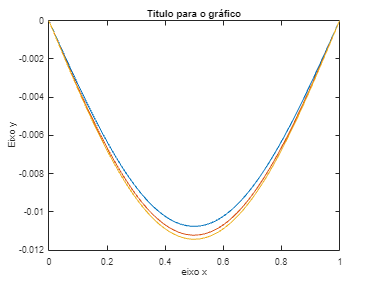

end